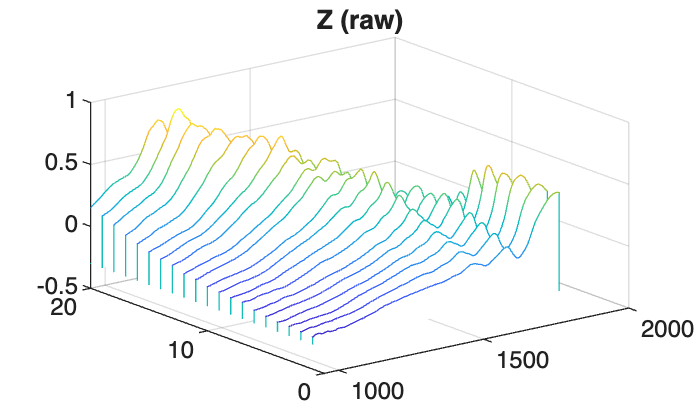

clear; clc;

wn        = 950:2:1800;
% fracMain:
%   Threshold used to select the main plasmonic region of each metasurface.
%   We shift each spectrum so min=0, then keep values >= fracMain * max.
%   Example: fracMain = 0.3  → keep top 70% of transmission.
%   This isolates the main resonance and removes low-signal regions.
fracMain  = 0.3;

% polyOrder:
%   Polynomial order for Savitzky–Golay smoothing / differentiation.
%   polyOrder = 3 means a cubic polynomial is fitted in each SG window.
%   Higher orders fit the data more flexibly but may amplify noise.
polyOrder = 3;

% baseWin:
%   Nominal SG window length (number of points). Must be odd.
%   The actual window per row will auto-shrink if the valid region is short.
%   Example: baseWin = 15 uses a 15-point window for the 2nd derivative.
%   Larger windows → smoother derivative; smaller windows → sharper peaks.
baseWin   = 15;

matFile = './extractedSpectra/all_Spectra_Sample_05.mat';



% Z      = raw averaged transmission per metasurface (20 x 426)
% Zlong  = main plasmonic resonance region per metasurface (NaNs outside)
% A2_long = 2nd-derivative absorbance, highlighting vibrational peaks
[Z, Zlong, A2_long] = process_one_sample(matFile, wn, fracMain, polyOrder, baseWin);

% quick plots
figure; waterfall(wn,1:20,Z); title('Z (raw)');

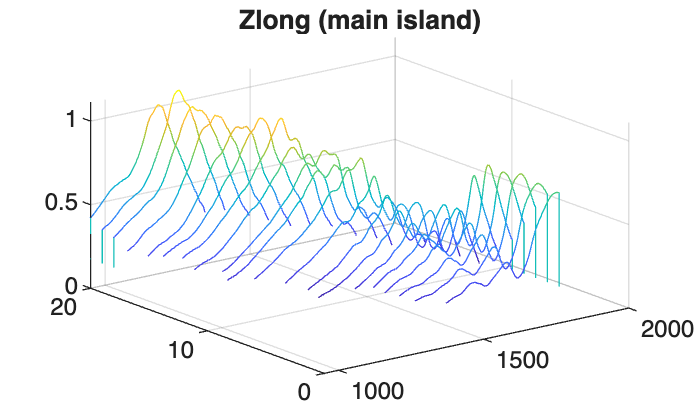

figure; waterfall(wn,1:20,Zlong); title('Zlong (main island)');

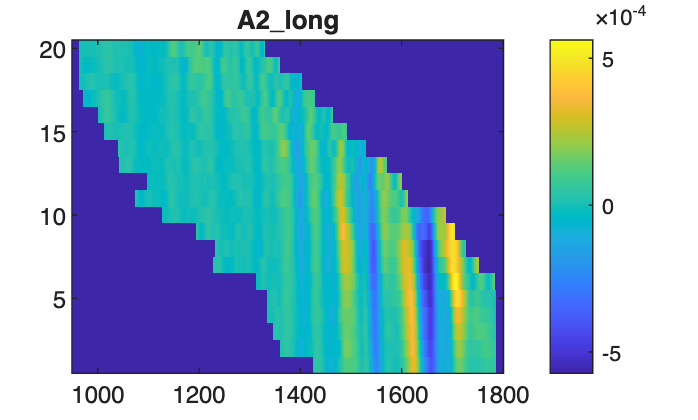

figure; imagesc(wn,1:20,A2_long); axis xy; colorbar; title('A2\_long');

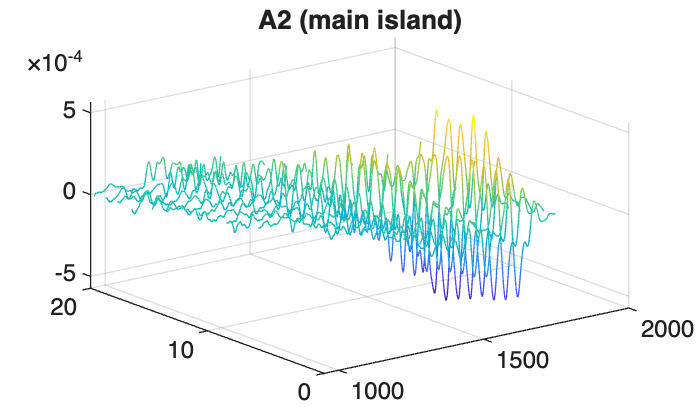

figure; waterfall(wn,1:20,A2_long);  title('A2 (main island)');

clear; clc;

wn        = 950:2:1800;
fracMain  = 0.3;
polyOrder = 3;
baseWin   = 15;

nSamples  = 22;
nSeg      = 20;
nWN       = numel(wn);

% Preallocate
Z_all      = nan(nSamples, nSeg, nWN);
Zlong_all  = nan(nSamples, nSeg, nWN);
A2_all     = nan(nSamples, nSeg, nWN);

for s = 1:nSamples
    
    if s <= 20

        matFile = sprintf('./extractedSpectra/all_Spectra_Sample_%02d.mat', s);

    else

        matFile = sprintf('./extractedSpectra/all_Spectra_Sample_N%d.mat', s-20);

    end

    % Z      = raw averaged transmission per metasurface (20 x 426)
    % Zlong  = main plasmonic resonance region per metasurface (NaNs outside)
    % A2_long = 2nd-derivative absorbance, highlighting vibrational peaks
    [Z, Zlong, A2_long] = process_one_sample(matFile, wn, fracMain, polyOrder, baseWin);

    Z_all(s,:,:)     = Z;
    Zlong_all(s,:,:) = Zlong;
    A2_all(s,:,:)    = A2_long;
end


%load all PFSamples dropcasted on CaF2 (absorbance)
load("./referenceCaF2/allPFSamples_baselineCorrected_znormalized.mat");
refCaF2_all = nan(nSamples, nWN);
%For second derivative
A2_refCaF2_all = nan(nSamples, nWN);
dt = wn(2) - wn(1);
for s = 1:nSamples
    
    if s <= 20
        vars = sprintf('PF%02d_baselineCorr_znorm_ref', s);
        refCaF2_all(s,:) = eval(vars);
        %power of 10 because sg_second_derivative expects transmittance
        A2_refCaF2_all(s,:) = sg_second_derivative(10.^(-eval(vars).'),...
            wn, polyOrder, baseWin, dt);
    else
        vars = sprintf('PFN%02d_baselineCorr_znorm_ref', s-20);
        refCaF2_all(s,:) = eval(vars);
        %power of 10 because sg_second_derivative expects transmittance
        A2_refCaF2_all(s,:) = sg_second_derivative(10.^(-eval(vars).'),...
            wn, polyOrder, baseWin, dt);
    end

end

%choose one and plot
s = 14;   % sample index
figure; imagesc(wn, 1:nSeg, squeeze(A2_all(s,:,:))); axis xy; colorbar;
title(sprintf('A2\\_long – Sample %02d', s));



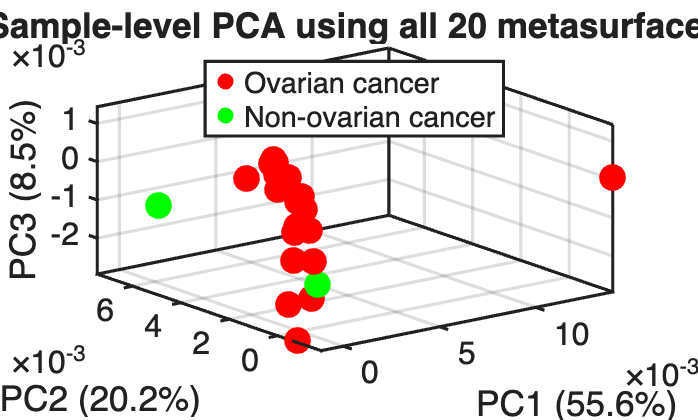

%PCA analysis

% data: 22 x 20 x 426

% reshape each sample into one row

X = reshape(A2_all, nSamples, []);   % 22 x 8520

% replace NaNs

X(isnan(X)) = 0;

% PCA

[coeff, score, latent, ~, explained] = pca(X);

% PC scores for 22 samples

PC1 = score(:,1);

PC2 = score(:,2);

PC3 = score(:,3);



% labels: 1 = cancer, 0 = non-cancer

labels = [ones(20,1); zeros(2,1)];

% split groups

idx_cancer = labels == 1;

idx_neg    = labels == 0;

figure; hold on;

% cancer = red

scatter3(PC1(idx_cancer), PC2(idx_cancer), PC3(idx_cancer), 100, 'r', 'filled');

% non-cancer = green

scatter3(PC1(idx_neg), PC2(idx_neg), PC3(idx_neg), 100, 'g', 'filled');

xlabel(sprintf('PC1 (%.1f%%)', explained(1)));

ylabel(sprintf('PC2 (%.1f%%)', explained(2)));

zlabel(sprintf('PC3 (%.1f%%)', explained(3)));

title('Sample-level PCA using all 20 metasurfaces');

legend({'Ovarian cancer', 'Non-ovarian cancer'}, 'Location', 'best');

grid on;

view(3)
set(gca, 'FontSize', 12, 'LineWidth', 1.2, 'Box', 'on');

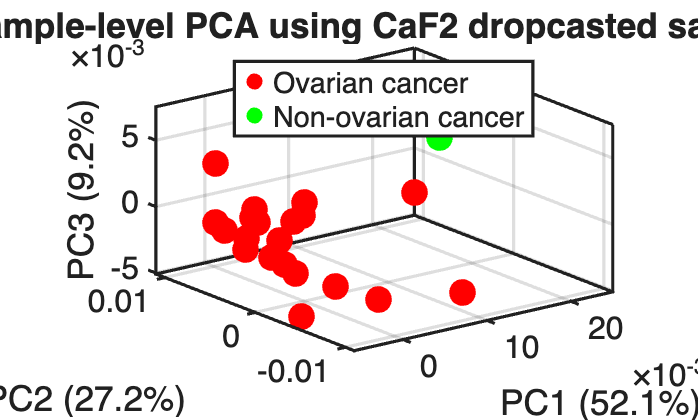

%PCA analysis for CaF2 sample 

% data: 22 x  426

% reshape each sample into one row

X_ref = A2_refCaF2_all; 

% replace NaNs

X_ref(isnan(X_ref)) = 0;

% PCA

[coeff, score, latent, ~, explained] = pca(X_ref);

% PC scores for 22 samples

PC1 = score(:,1);

PC2 = score(:,2);

PC3 = score(:,3);



% labels: 1 = cancer, 0 = non-cancer

labels = [ones(20,1); zeros(2,1)];

% split groups

idx_cancer = labels == 1;

idx_neg    = labels == 0;

figure; hold on;

% cancer = red

scatter3(PC1(idx_cancer), PC2(idx_cancer), PC3(idx_cancer), 100, 'r', 'filled');

% non-cancer = green

scatter3(PC1(idx_neg), PC2(idx_neg), PC3(idx_neg), 100, 'g', 'filled');

xlabel(sprintf('PC1 (%.1f%%)', explained(1)));

ylabel(sprintf('PC2 (%.1f%%)', explained(2)));

zlabel(sprintf('PC3 (%.1f%%)', explained(3)));

title('Sample-level PCA using CaF2 dropcasted samples');

legend({'Ovarian cancer', 'Non-ovarian cancer'}, 'Location', 'best');

grid on;

view(3)
set(gca, 'FontSize', 12, 'LineWidth', 1.2, 'Box', 'on');